# Sample 7-6

## 幾何学処理

幾何学的変換

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Geometric image processing

Geometric transformations

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 画像入力

(Image input)

% Reading an image
fixed = imread('westconcordorthophoto.png');

シフト画像の生成 (Generation of shifted image)

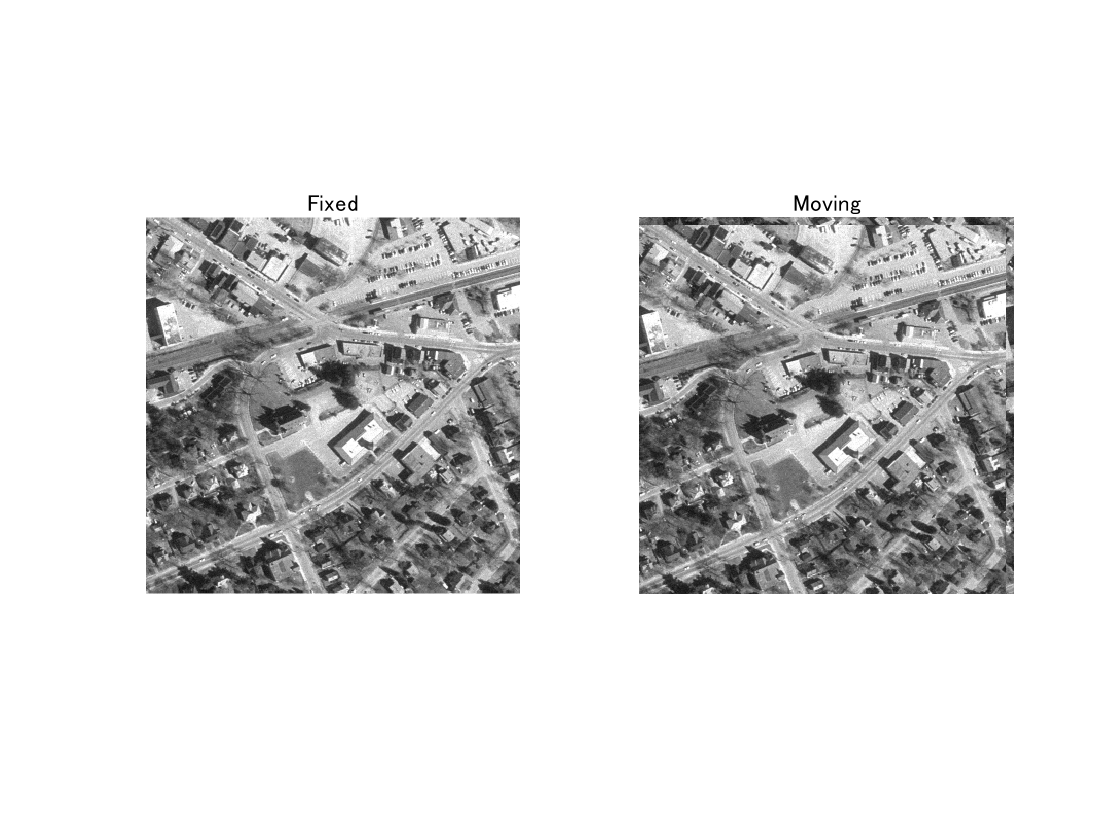

% Setting the amount of movement
mx = -8;
my = 8;

% (Circulary) shifting the image
moving = circshift(fixed,[my mx]);

% Show the images
figure(1)
subplot(1,2,1)
imshow(fixed)
title('Fixed')
subplot(1,2,2)
imshow(moving)
title('Moving')

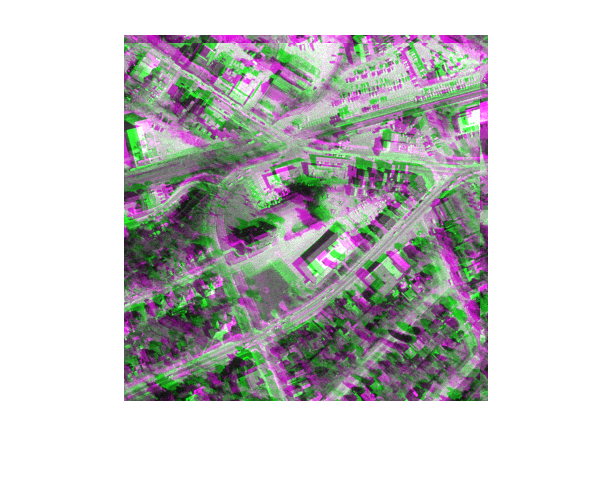


% Show difference of the images
figure(2)
imshowpair(moving,fixed)

### 位相限定相関

(Phase only correlation)

2枚の画像の位置ずれ量を位相特性から検出．(Detects the amount of displacement between two images from their phase characteristics.)

        
$$\mathrm{POC}(\{x[\mathbf{n}]\}_\mathbf{n},\{y[\mathbf{n}]\}_\mathbf{n})=\mathrm{IDSFT}\left(\frac{{X}(e^{\j\omega})\overline{Y(e^{\j\omega})}}{|X(e^{\j\omega})\overline{Y(e^{\j\omega})}|}\right)=\mathrm{IDSFT}\left(e^{\j(\angle X(e^{\j\omega})-\angle Y(e^{\j\omega}))}\right)$$


【参考資料】(Reference)

- [http://www.aoki.ecei.tohoku.ac.jp/~ito/vol1_030.pdf](http://www.aoki.ecei.tohoku.ac.jp/~ito/vol1_030.pdf)

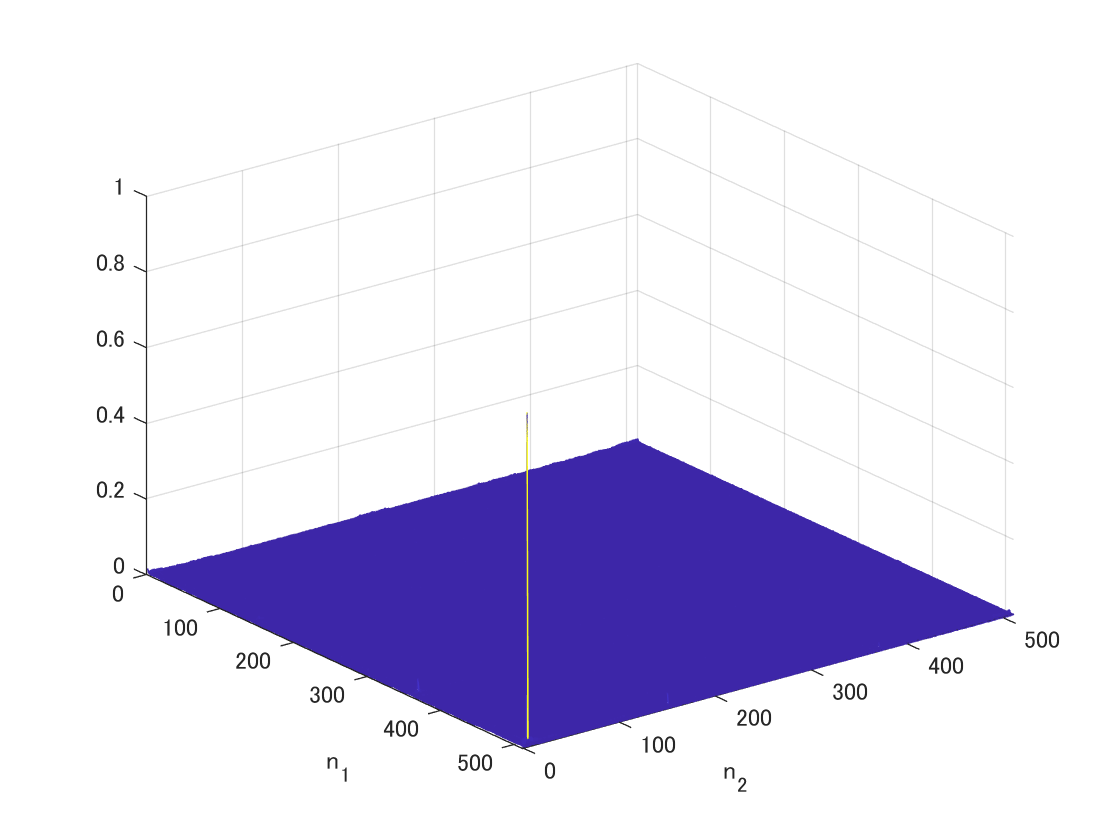

% Definition of POC in frequency domain
nPoints = pow2(nextpow2(size(fixed)));
frqPoc = @(x,y) exp(1j*(angle(fftn(x,nPoints))-angle(fftn(y,nPoints))));

% POC Evaluation between two images
poc = abs(ifftn(frqPoc(moving,fixed)));

% POC result
[n1,n2] = ndgrid(1:nPoints(1),1:nPoints(2));
figure(3)
mesh(n1,n2,poc)
xlabel('n_2')
ylabel('n_1')
axis ij
ax = gca;
ax.XLim = [0 nPoints(2)-1];
ax.YLim = [0 nPoints(1)-1];

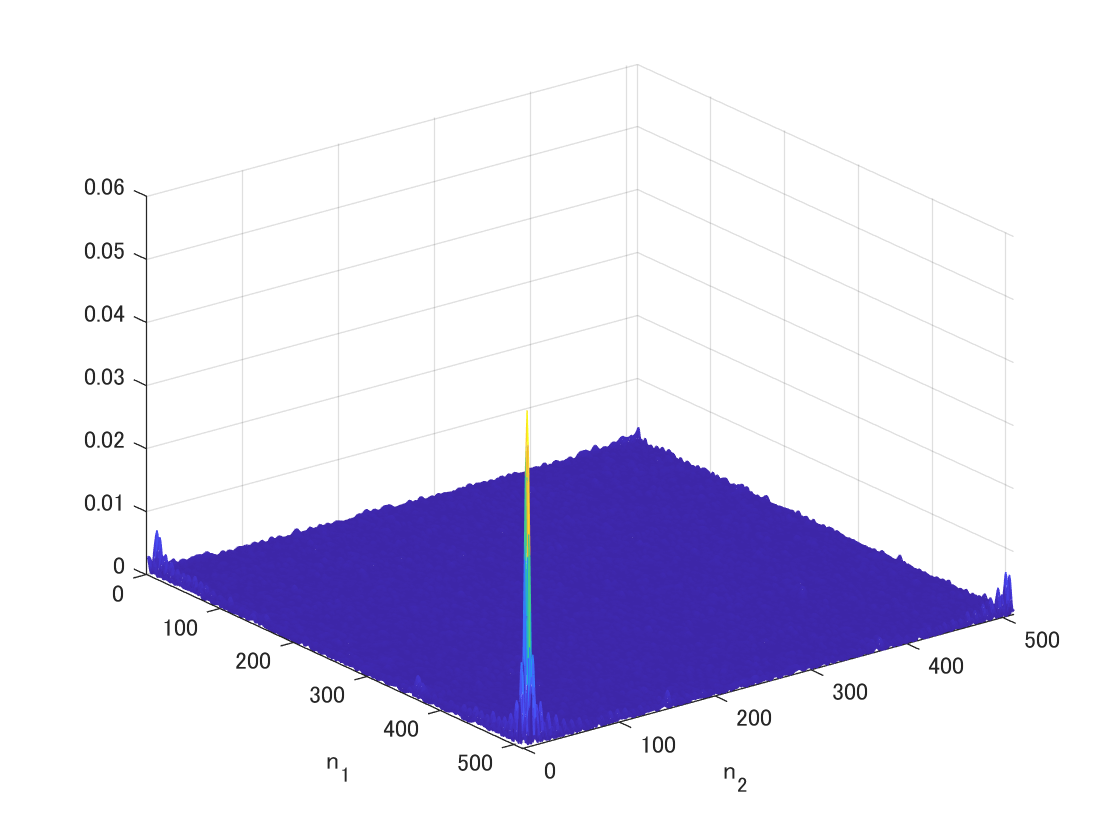

% POC result with band limitation for denoising
szRect = nPoints/4;
frqMask = zeros(nPoints);
frqMask(1:szRect,1:szRect) = ones(szRect);
frqMask = circshift(frqMask,-ceil(szRect/2));

% POC Evaluation between two images with band limitation
poc = abs(ifftn(frqMask.*frqPoc(moving,fixed)));

% POC result with band limitation
figure(4)
mesh(n1,n2,poc)
xlabel('n_2')
ylabel('n_1')
axis ij
ax = gca;
ax.XLim = [0 nPoints(2)-1];
ax.YLim = [0 nPoints(1)-1];

% Find the peak
[~,loc]= max(poc(:));
py = mod(loc,nPoints(1));
px = floor(loc/nPoints(1));

% Taking account of the negative shifot
py = mod(py+nPoints(1)/2,nPoints(1))-nPoints(1)/2;
px = mod(px+nPoints(2)/2,nPoints(2))-nPoints(2)/2;
disp(['The peak location is [px, py] = [ ' num2str(px) ' ' num2str(py) ' ]'])

The peak location is [px, py] = [ -8 9 ]


### 画像レジストレーション

(Image registration)

位置のずれた2枚の画像の位置合わせを実行する．(Performs registration of two misaligned images.)

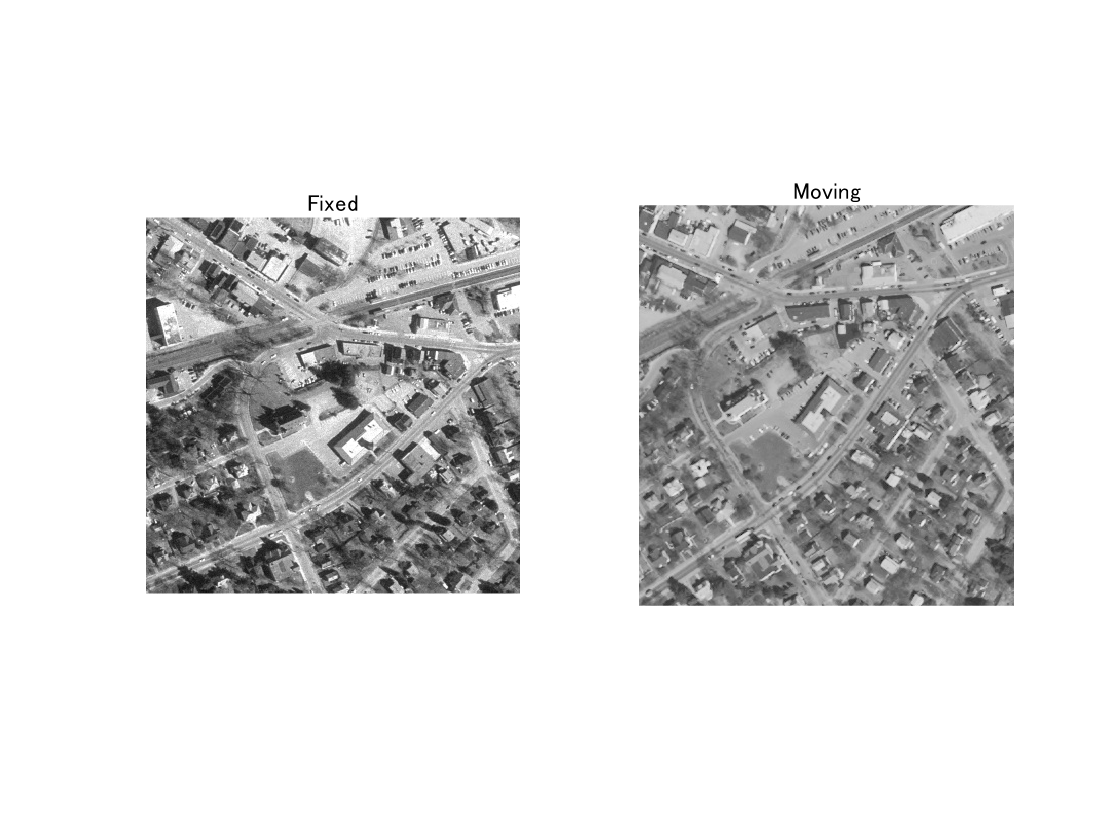

% Actual moving picture
moving = rgb2gray(imread('westconcordaerial.png'));

% Show the images
figure(5)
subplot(1,2,1)
imshow(fixed)
title('Fixed')
subplot(1,2,2)
imshow(moving)
title('Moving')

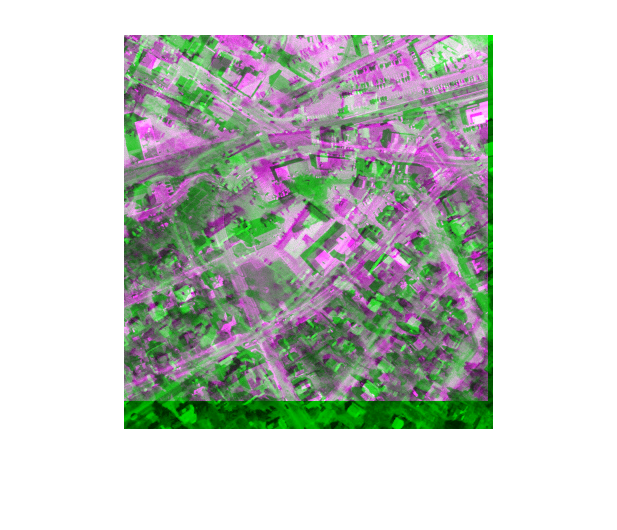


% Show difference of the images
figure(6)
imshowpair(moving,fixed)

幾何学的変換の推定(Estimation of geometric transformations)

tformEstimate = imregcorr(moving,fixed);

座標情報 (Information on the coordinate)

Rfixed = imref2d(size(fixed));

レジストレーション (Registration)

movingReg = imwarp(moving,tformEstimate,'OutputView',Rfixed);

結果の表示 (Display result)

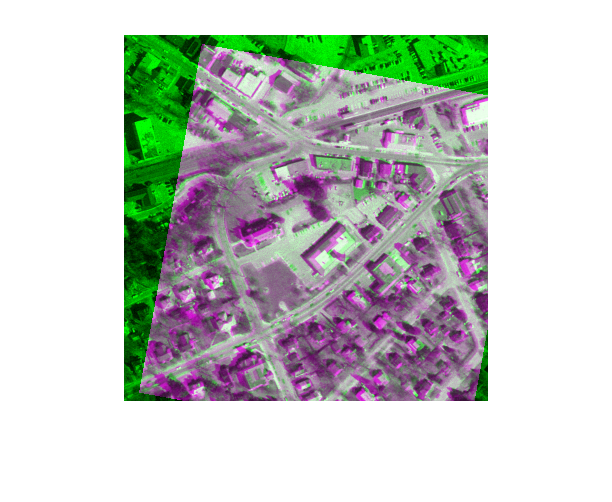

imshowpair(fixed,movingReg);

© Copyright, Shogo MURAMATSU, All rights reserved.